# Spreading the butter to solve the diffusion equation

We're going to simulate diffusion of N0 molecules, starting in the middle of an *E. coli* cell, using the analytical solution to the diffusion equation provided in Homework 4. First, let's define the model parameters.

N0=100;             %initial number of molecules in the center box
D=0.01;             %diffusion constant in um^2/ms
L=1;                %length of half of the cell in um

The simulation parameters are

dx=0.01;                         %in um
M=L/dx;                          %number of imaginary boxes in the E. coli cell
TimePoints=[0.01,0.1,1,5,10];    %time points in ms
TimeSteps=5;                     %number of time points

Now we need to define the matrix we'll use to keep track of the molecules as well as the initial condition. The matrix N we'll use has 5 rows (number of time points) and M columns (number of imaginary boxes).

N(1:TimeSteps,1:M)=0;

We're ready to run the simulation. I'm going to need two for-loops, one that goes over time and one that goes over the box number.

for j=1:TimeSteps
    c0 = N0/sqrt(4*pi*D*TimePoints(j));
    x=0;
    for i=1:M
       c=c0*exp(-(x^2)/(4*D*TimePoints(j)));
       x=x+dx;
       N(j, i)=c;
    end
end

Finally, let's plot the distribution at each different time point. To do this, I create a vector that keeps track of the box number.

Box=1:M;

Now plot the profile at the each time point. This means grabbing all columns along the each row of N. 

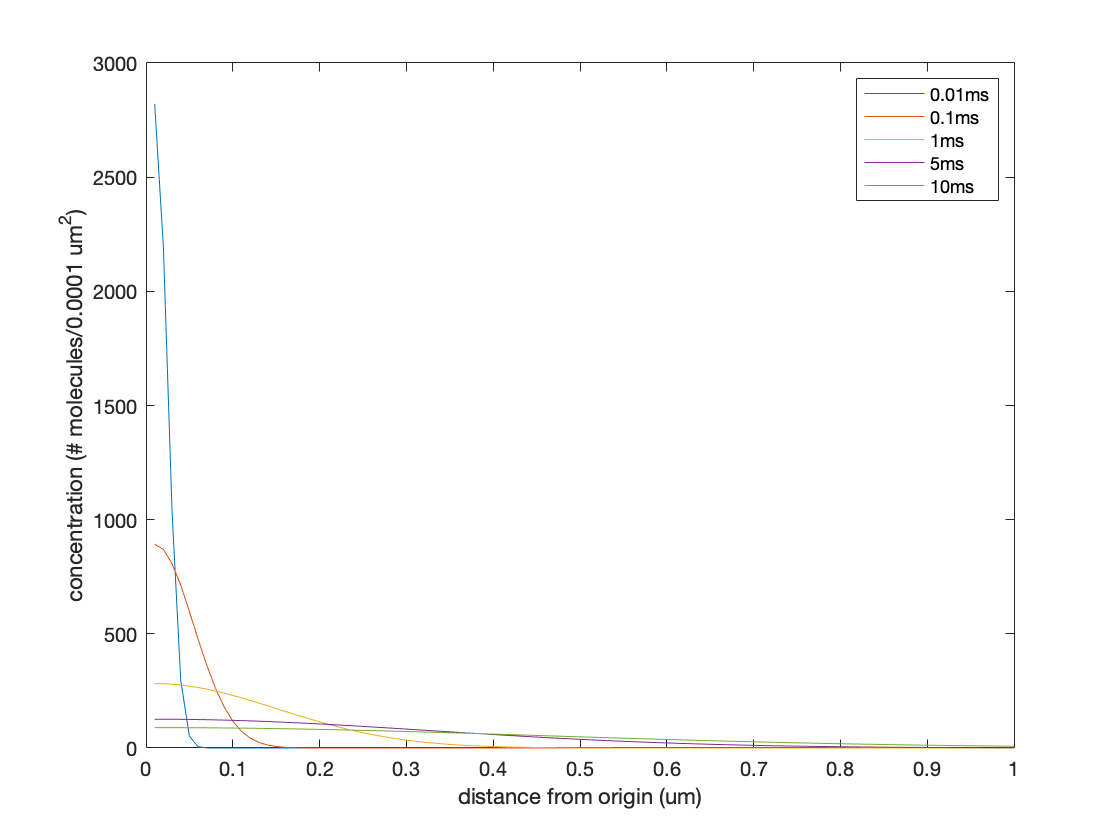

plot(Box/100, N(1,:))
hold on
plot(Box/100, N(2,:))
plot(Box/100, N(3,:))
plot(Box/100, N(4,:))
plot(Box/100, N(5,:))
hold off
xlabel('distance from origin (um)')
ylabel('concentration (# molecules/0.0001 um^2)')
legend('0.01ms', '0.1ms', '1ms', '5ms', '10ms')